Problem 1

A)

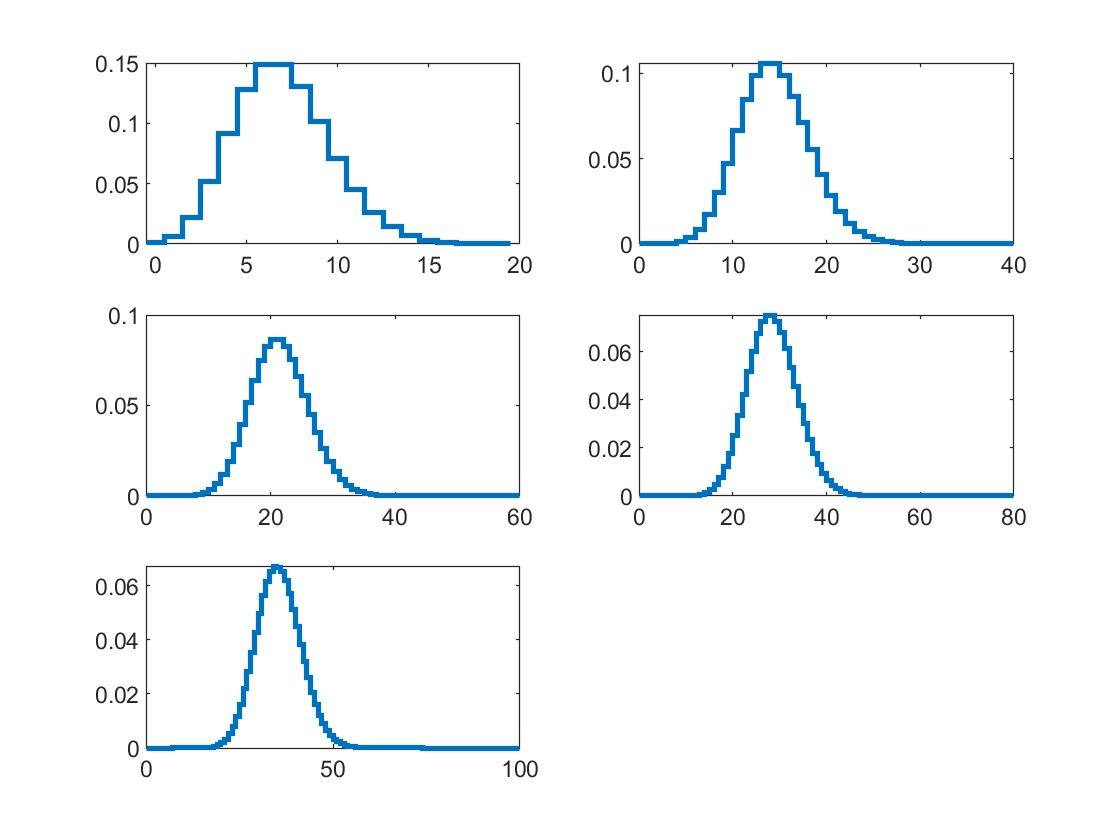

cosmic = makedist("Poisson",'lambda',7);
x = 0:20;
u = pdf(cosmic,x);
v = u;
subplot(3,2,1)
stairs(x-0.5,u,"LineWidth",2)
for i = 1:4
    dayx = conv(u,v);
    x = 0:20*(i+1);
    subplot(3,2,i+1)
    stairs(x,dayx,"LineWidth",2)
    u = dayx;
end

B)

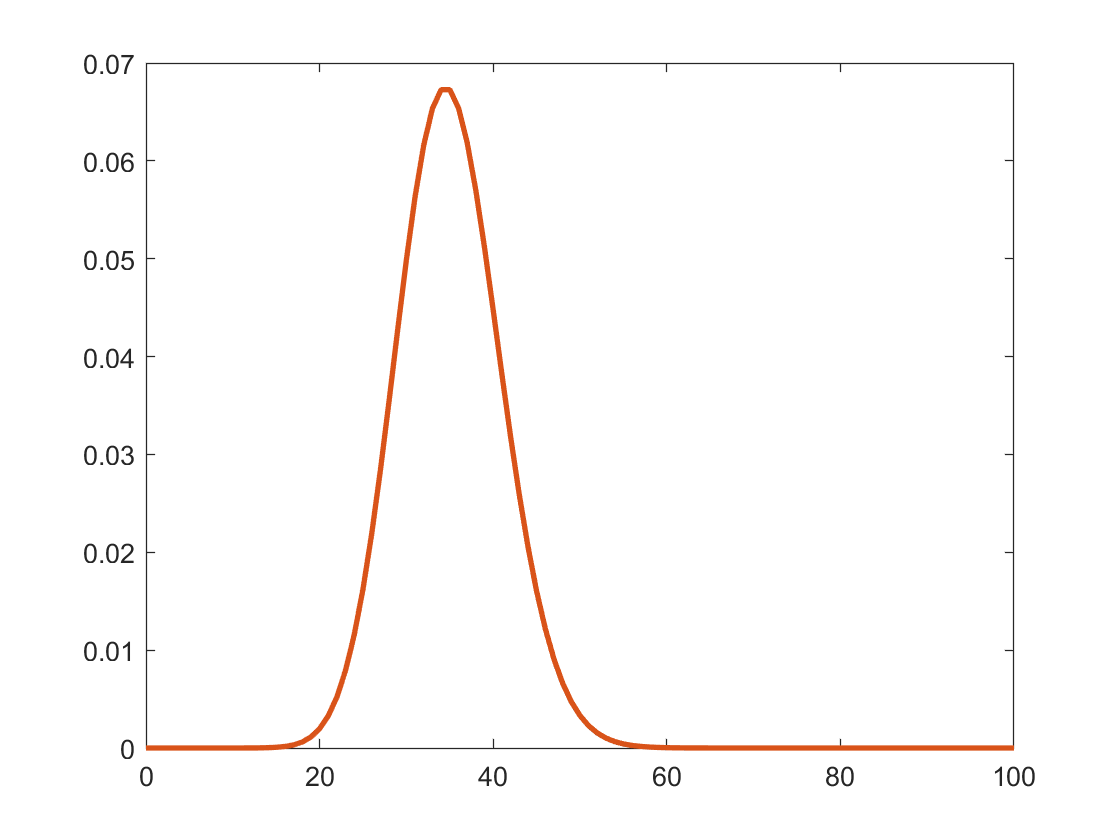

poissontest = makedist("Poisson", 'lambda',7*5);
ytest = pdf(poissontest,x);
subplot(1,1,1)
plot(x,u,x,ytest,"LineWidth",2)

sum(ytest-u)

ans = 7.2475e-05

Because the sum of the difference between the Poisson distribution after 5 days and the test Poisson distribution with 7 * 5 as the mean value is so small with e-05, they are basically the same. Therefore the summed probability distribution is still a Poisson distribution.

C)

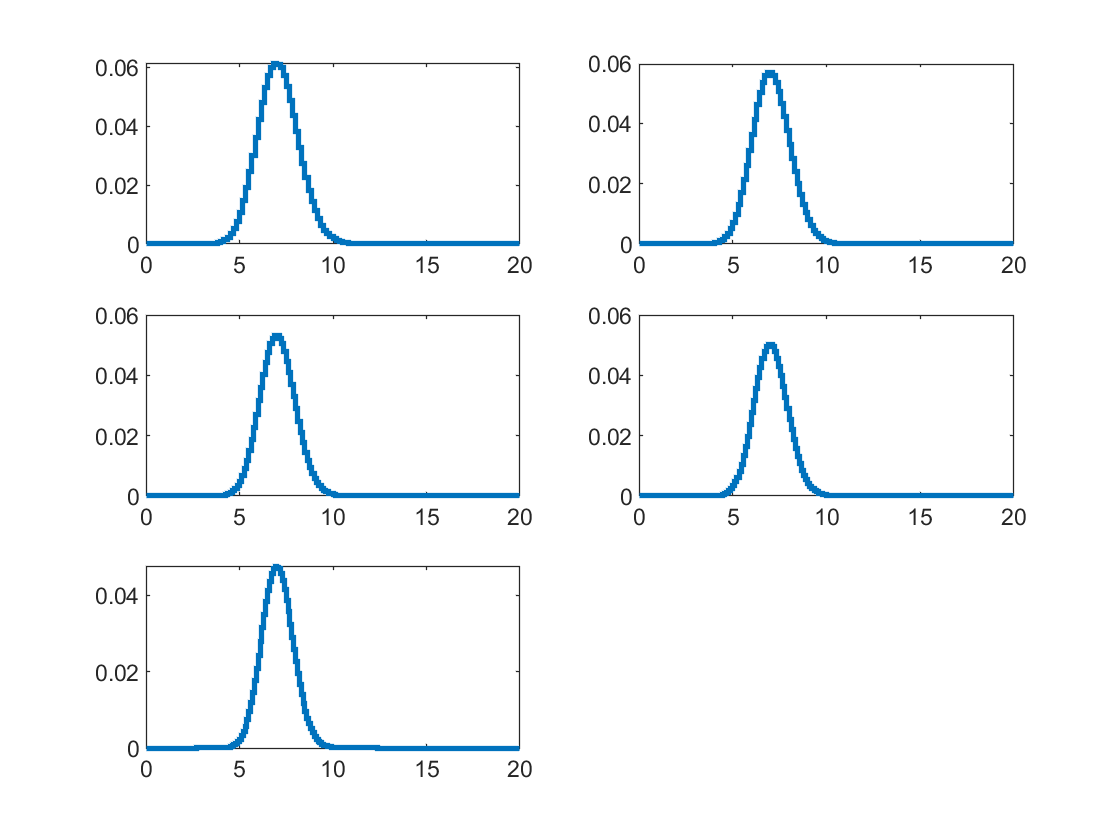

for i = 5:9
    dayx = conv(u,v);
    x = 0:20*(i+1);
    subplot(3,2,i-4)
    stairs(x/(i+1),dayx,"LineWidth",2)
    u = dayx;
end

It becomes much more like a Gaussian Distribution as the number of days becomes larger. In part B, the Poisson Distribuion after 5 days in almost a Gaussian Distribution if we plot it with lines but not stairs. As we averaged it, we got more steps between integers and it just basically becoming a Gaussian Distribution. Also, the central limit theorem stated that when distributions are added, their sum tends towards a Gaussian Distribution.

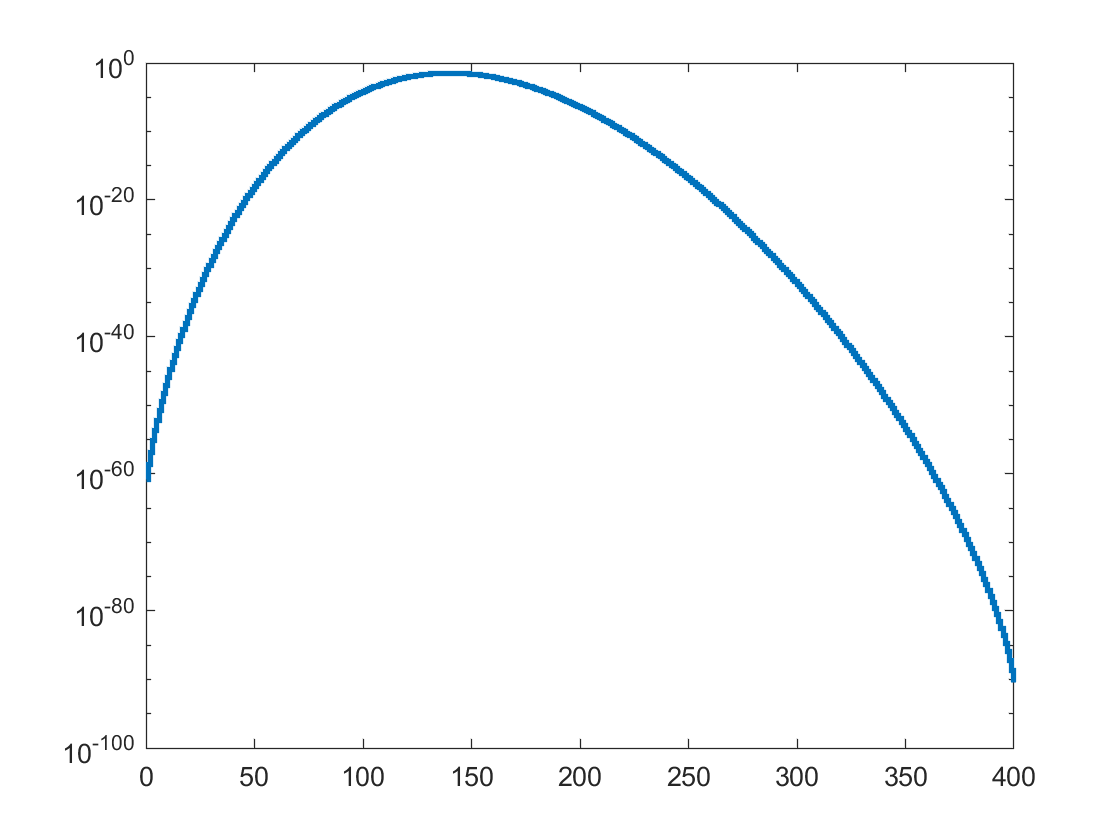

for i = 10:19
    dayx = conv(u,v);
    x = 0:20*(i+1);
    u = dayx;
end
subplot(1,1,1)
stairs(x,dayx,"LineWidth",2)
set(gca,'YScale','log')

cosmic20 = makedist("Poisson",'lambda',7*20);
gamma = 10 * 20;
p = cdf(cosmic20,gamma);
sigma = norminv(p)

sigma = 4.8120

Problem 2

A)

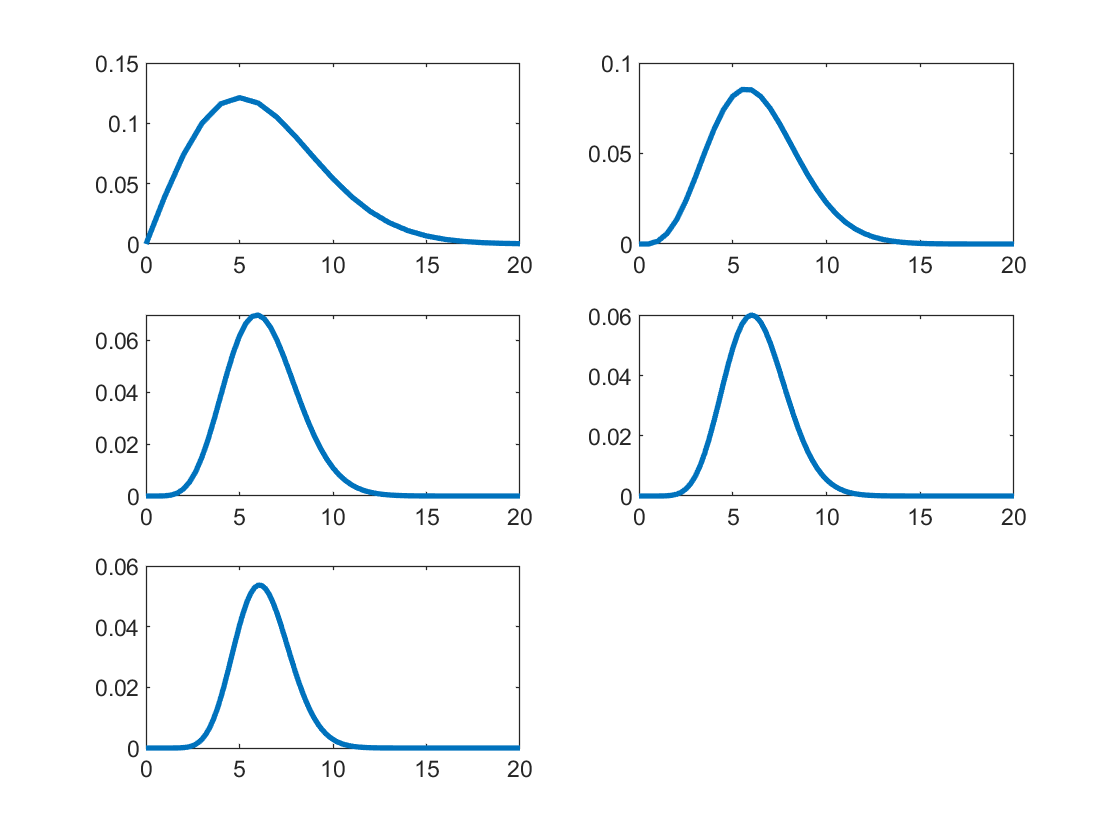

rayl = makedist("Rayleigh",'b',5);
x = 0:20;
u = pdf(rayl,x);
v = u;
subplot(3,2,1)
plot(x,u,"LineWidth",2)
for i = 1:4
    raylp = conv(u,v);
    x = 0:20*(i+1);
    subplot(3,2,i+1)
    plot(x/(i+1),raylp,"LineWidth",2)
    u = raylp;
end

B) Yes. after about 2 iteration of averages, the distribution curve is much likely to be an Gaussian Distribution.

Problem 3

image = makedist("Normal",'mu',50,"sigma",10)

image =   NormalDistribution

  Normal distribution
       mu = 50
    sigma = 10


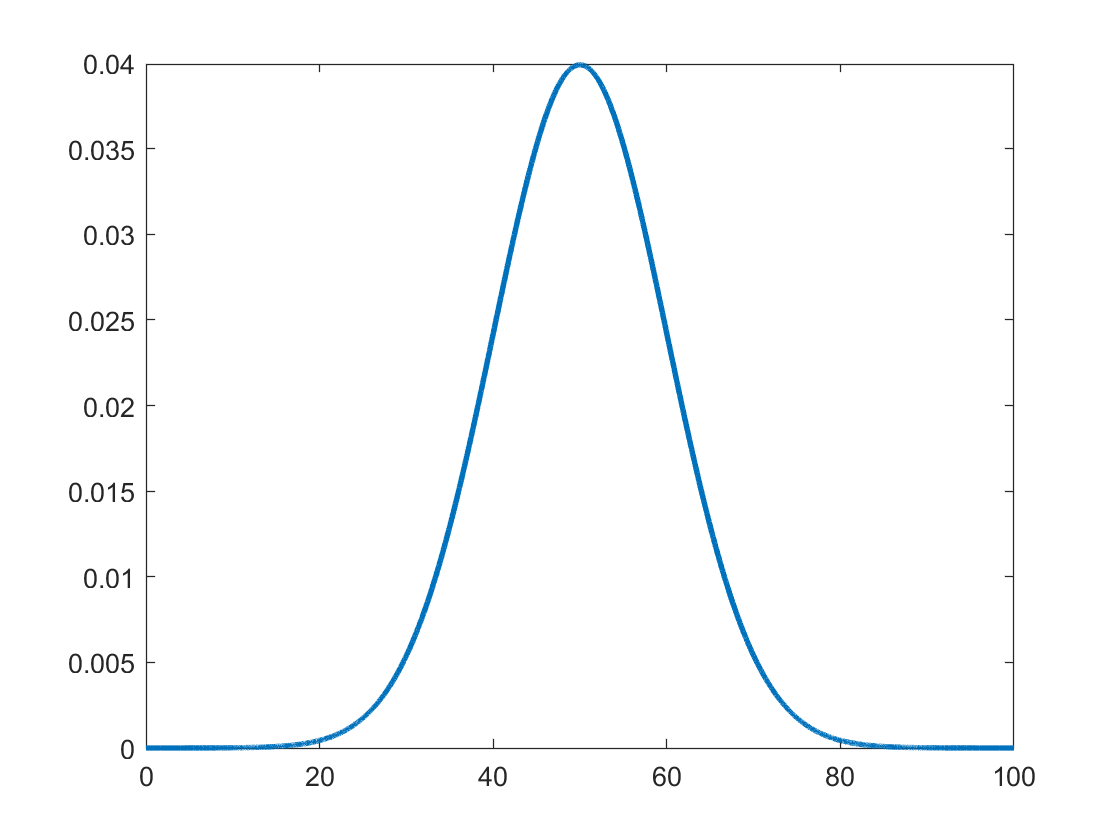

xpixel = linspace(0,100,10000);
subplot(1,1,1)
plot(xpixel,pdf(image,xpixel),"LineWidth",2)